clear vars; close all; clc
format long
global A B C G P Z fre nn gamma x_eq tau

nn = 3;           % number of ring cells
flag = 2;         % 0 - regular ring, 1 - NONregular network, 2 - directed network
mp = 1.0;
ifi = 0;
tend = 2000;      % time 

%% Individual Dynamics

A = [1 -1 1; 1 0 0; -4 2 -3];
B = [0;0;1];
C = [0 0 1];
P = lyap(A',eye(length(A)));
Z = B'*P;

### Network Structure

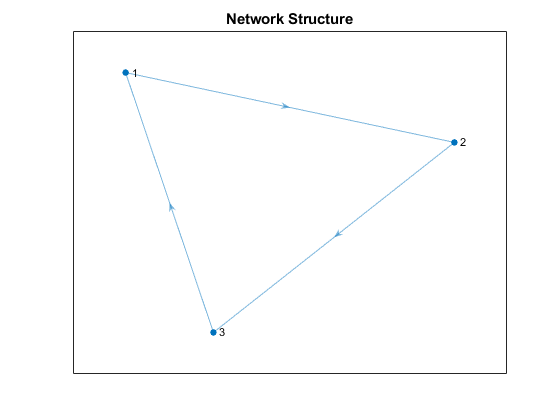

[G,n,offset] = NetworkStructure(nn,flag);

In=eye(n);

### Equilibrium point(s) and Linearizaton

syms x1 x2 x3  s zu
assume (x1, 'real')
assume (x2, 'real')
assume (x3, 'real')

x = [x1;x2;x3];

J(x) = jacobian(A*x- B*Z*x.^3);
eqp = solve((A*x- B*Z*x.^3==0),x);
x_eq = [double(eqp.x1); double(eqp.x2); double(eqp.x3)];
J0 = double(J(eqp.x1, eqp.x2, eqp.x3));
huzwitzCrit(J0)

System is Stable



H(s) = C*((s*eye(length(J0)) - J0)^-1)*B;
H(s) = simplify(H(s));

w = 0:0.0001:1;

L = double(H(1i*w'));

[nu,i] = min(real(L));

om_star = w(i);
gamma_min = -1/(2*nu)

gamma_min =    0.648118932664360



% return
BC = B*C;

AA = kron(In,(J0-gamma_min*BC));
BB = kron(gamma_min*G,BC);

% eq1 = det(kronsum((AA + BB*zu),(AA'+ BB'*(1/zu))));
% crit1 = double(solve(eq1==0,zu));
% crit1m=[];
% f1=[];
% for i = 1:length(crit1)
%     ei = eig(AA + BB*crit1(i));
%     for ii = 1:length(ei)
%         if abs(real(ei(ii)))<10e-6 && imag(ei(ii))>0 
%             crit1m = [crit1m; crit1(i)];
%             f1 = [f1; imag(ei(ii))];
%         end
%     end   
% end
% 
% taus = sort((-1i*log(1./crit1m))./f1);
% taus = real(taus(taus>0))

### Most rigth eigenvalue of linearization


addpath('files_roots')  

% gamma = 1.1*gamma_min
% tau = taus(1)

gamma = 0.7129

gamma =    0.712900000000000


tau = 1.5304

tau =    1.530400000000000


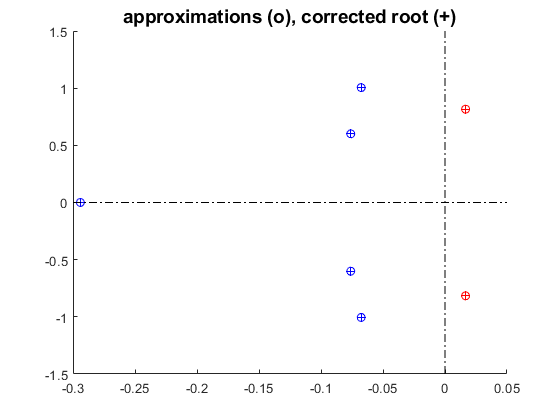


A0 = kron(In,(J0 - gamma*B*C));
A1 = kron(gamma*G,B*C);
hA = [0, tau];

tds = tds_create({A0, A1}, hA);
tds_check_valid(tds)
options=tdsrootsoptions;
options.minimal_real_part= -0.3;
[eigenvalues, N, size_eigenvalue_problem]=tds_charateristic_roots(tds, options);
figure(2)
eigenplot(eigenvalues)

eigenvalues.l1

ans =   0.016702796253648 + 0.816293897679189i
  0.016702796253648 - 0.816293897679189i
 -0.067499488139830 + 1.005527410091328i
 -0.067499488139830 - 1.005527410091328i
 -0.075972610340448 + 0.600653216426968i
 -0.075972610340448 - 0.600653216426968i
 -0.294066723216651 + 0.000000000000000i


eigenvalues.l0

ans =   0.016586027085729 + 0.816315983082527i
  0.016586027085729 - 0.816315983082527i
 -0.067617293552668 + 1.005140588650575i
 -0.067617293552668 - 1.005140588650575i
 -0.076008631384696 + 0.600692115215507i
 -0.076008631384696 - 0.600692115215507i
 -0.294066723216659 + 0.000000000000000i


% return

fre = imag(eigenvalues.l1(1))

fre =    0.816293897679189


## dde23

%   return

% IC = @centhist;
% tic
% options = ddeset('RelTol',1e-3);
% sol = dde23(@centipide,tau,IC,[0, tend],options);
% toc
% dde_z = kron(eye(n),Z)*sol.y;
% dde_zs = dde_z + fliplr(offset)';
% time = sol.x;
% 
% figure;
% plot(time,dde_z)
% title('Centipede with delayed coupling');
% xlabel('time t');
% ylabel('solution z');
% ylim([-1 1])
% grid on
% 
% [omega_s, T_s, amp_s, fi_s, DC_s] = osciprof(dde_z,time,n);
% 
% q_s = amp_s.*exp(1i*fi_s);
% y_s = DC_s + q_s;
% g_s = [fi_s;amp_s;DC_s;omega_s];


%return

## Equal amplitude case


om = fre

om =    0.816293897679189


tic

Wz = Z*((1i*om*eye(length(A)) - A)^-1)*B;
Wz0 = Z*((0*eye(length(A)) - A)^-1)*B;

Wy = C*((1i*om*eye(length(A)) - A)^-1)*B;
Wy0 = C*((0*eye(length(A)) - A)^-1)*B;

[v,lam]=eig(G,'vector');

lam_max=max(real(lam))

lam_max =    1.000000000000000



ii=2

ii =      2



% kappa = (gamma*exp(-1i*om*tau)*lam(3)*Wy - gamma*Wy - 1)/Wz

 [omega_test, kappa] = kappaFre_cent(A,B,C,Z,lam(ii),tau,om,gamma);

amp=sqrt((4*kappa)/3)

amp =    0.324924606639876



omega = om

omega =    0.816293897679189



LKI = G-lam(ii)*In;

[vi,lamda]=eig(LKI,'vector');

q = vi(:,ii);
fi=angle(q)

fi =    2.094395102393196
                   0
  -2.094395102393196


fideg = rad2deg(fi)

fideg = 	1.0e+02 *

   1.200000000000000
                   0
  -1.200000000000000


toc

Elapsed time is 1.002784 seconds.



dAmp = 100*norm(amp-amp_s)/norm(amp_s)

Undefined function or variable 'amp_s'.

dOmega = 100*norm(omega-omega_s)/norm(omega_s)



% k_test = (gamma*exp(-1i*om*tau)*lam(ii)*Wy - gamma*Wy - 1)/Wz

% syms k_test
% 
% % assume(k_test,'real')
% % assume(k_test>0)
% 
% eque = det(1i*om*eye(3) - A + B*(k_test*Z + gamma*C - gamma*exp(-1i*om*tau)*lam(ii)*C));
% DF_val = real(double(solve(eque==0,k_test)))
% 
% amp_test=sqrt((4*DF_val)/3)
% 
% dAmp_test = 100*norm(amp_test-amp_s)/norm(amp_s)